%% Initialisation
clc
clearvars 
close all   

% Set LaTeX as default interpreter for axis labels, ticks and legends
set(0,'defaulttextinterpreter','latex')
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

set(0,'DefaultFigureWindowStyle','docked');
set(0,'defaultAxesFontSize',  16)
set(0,'DefaultLegendFontSize',16)

addpath('tyre_lib/')


to_rad = pi/180;
to_deg = 180/pi;

%% Select tyre dataset - PURE LONGITUDINAL
%dataset path
data_set_path = 'dataset/';
% dataset selection and loading

%data_set = 'Hoosier_B1464run23'; % pure lateral forces
data_set = 'Hoosier_B1464run30';  % braking/traction (pure log. force) + combined

% tyre geometric data:
% Hoosier 20.5x7.0 - 13 R25B
% 13 diameter in inches
% 7.0 section width in inches
% tread width in inches
diameter = 13*2.56; %
Fz0 = 220;   % [N] nominal load is given
R0  = diameter/2/100; % [m] get from nominal load R0 (m) *** TO BE CHANGED ***


fprintf('Loading dataset ...')

Loading dataset ...

switch data_set
  case 'Hoosier_B1464run23'
  load ([data_set_path, 'Hoosier_B1464run23.mat']); % pure lateral
  cut_start = 27760;
  cut_end   = 54500;
  case 'Hoosier_B1464run30'
  load ([data_set_path, 'Hoosier_B1464run30.mat']); % pure longitudinal
  cut_start = 19028;
  cut_end   = 37643;
  otherwise 
  error('Not found dataset: `%s`\n', data_set) ;
  
end

% select dataset portion
smpl_range = cut_start:cut_end;

fprintf('completed!\n')

completed!


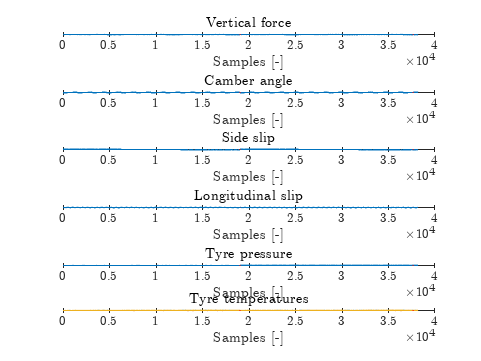


%% Plot raw data

figure
tiledlayout(6,1)

ax_list(1) = nexttile; y_range = [min(min(-FZ),0) round(max(-FZ)*1.1)];
plot(-FZ)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list(2) = nexttile; y_range = [min(min(IA),0) round(max(IA)*1.1)];
plot(IA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(3) = nexttile; y_range = [min(min(SA),0) round(max(SA)*1.1)];
plot(SA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Side slip')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(4) = nexttile; y_range = [min(min(SL),0) round(max(SL)*1.1)];
plot(SL)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Longitudinal slip')
xlabel('Samples [-]')
ylabel('[-]')

ax_list(5) = nexttile; y_range = [min(min(P),0) round(max(P)*1.1)];
plot(P)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre pressure')
xlabel('Samples [-]')
ylabel('[Pa]')

ax_list(6) = nexttile;  y_range = [min(min(TSTC),0) round(max(TSTC)*1.1)];
plot(TSTC,'DisplayName','Center')
hold on
plot(TSTI,'DisplayName','Internal')
plot(TSTO,'DisplayName','Outboard')
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre temperatures')
xlabel('Samples [-]')
ylabel('[degC]')

linkaxes(ax_list,'x')

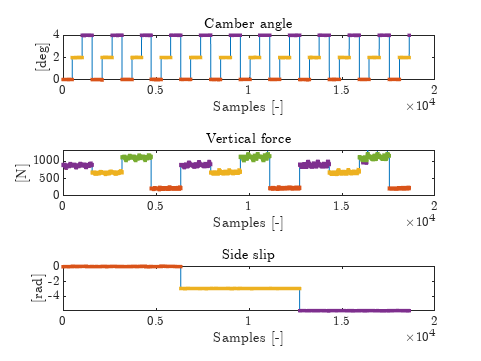



%plot(SA,FY)


%% Select some specific data
% Cut crappy data and select only 12 psi data

vec_samples = 1:1:length(smpl_range);
tyre_data = table(); % create empty table
% store raw data in table
tyre_data.SL =  SL(smpl_range);
tyre_data.SA =  SA(smpl_range)*to_rad;
tyre_data.FZ = -FZ(smpl_range);  % 0.453592  lb/kg
tyre_data.FX =  FX(smpl_range);
tyre_data.FY =  FY(smpl_range);
tyre_data.MZ =  MZ(smpl_range);
tyre_data.IA =  IA(smpl_range)*to_rad;

% Extract points at constant inclination angle
GAMMA_tol = 0.05*to_rad;
idx.GAMMA_0 = 0.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 0.0*to_rad+GAMMA_tol;
idx.GAMMA_1 = 1.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 1.0*to_rad+GAMMA_tol;
idx.GAMMA_2 = 2.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 2.0*to_rad+GAMMA_tol;
idx.GAMMA_3 = 3.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 3.0*to_rad+GAMMA_tol;
idx.GAMMA_4 = 4.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 4.0*to_rad+GAMMA_tol;
idx.GAMMA_5 = 5.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 5.0*to_rad+GAMMA_tol;
GAMMA_0  = tyre_data( idx.GAMMA_0, : );
GAMMA_1  = tyre_data( idx.GAMMA_1, : );
GAMMA_2  = tyre_data( idx.GAMMA_2, : );
GAMMA_3  = tyre_data( idx.GAMMA_3, : );
GAMMA_4  = tyre_data( idx.GAMMA_4, : );
GAMMA_5  = tyre_data( idx.GAMMA_5, : );

% Extract points at constant vertical load
% Test data done at: 
%  - 50lbf  ( 50*0.453592*9.81 =  223N )
%  - 150lbf (150*0.453592*9.81 =  667N )
%  - 200lbf (200*0.453592*9.81 =  890N )
%  - 250lbf (250*0.453592*9.81 = 1120N )

FZ_tol = 100;
idx.FZ_220  = 220-FZ_tol < tyre_data.FZ & tyre_data.FZ < 220+FZ_tol;
idx.FZ_440  = 440-FZ_tol < tyre_data.FZ & tyre_data.FZ < 440+FZ_tol;
idx.FZ_700  = 700-FZ_tol < tyre_data.FZ & tyre_data.FZ < 700+FZ_tol;
idx.FZ_900  = 900-FZ_tol < tyre_data.FZ & tyre_data.FZ < 900+FZ_tol;
idx.FZ_1120 = 1120-FZ_tol < tyre_data.FZ & tyre_data.FZ < 1120+FZ_tol;
FZ_220  = tyre_data( idx.FZ_220, : );
FZ_440  = tyre_data( idx.FZ_440, : );
FZ_700  = tyre_data( idx.FZ_700, : );
FZ_900  = tyre_data( idx.FZ_900, : );
FZ_1120 = tyre_data( idx.FZ_1120, : );

% The slip angle is varied continuously between -4 and +12° and then
% between -12° and +4° for the pure slip case

% The slip angle is varied step wise for longitudinal slip tests
% 0° , - 3° , -6 °
SA_tol = 0.5*to_rad;
idx.SA_0    =  0-SA_tol          < tyre_data.SA & tyre_data.SA < 0+SA_tol;
idx.SA_3neg = -(3*to_rad+SA_tol) < tyre_data.SA & tyre_data.SA < -3*to_rad+SA_tol;
idx.SA_6neg = -(6*to_rad+SA_tol) < tyre_data.SA & tyre_data.SA < -6*to_rad+SA_tol;
SA_0     = tyre_data( idx.SA_0, : );
SA_3neg  = tyre_data( idx.SA_3neg, : );
SA_6neg  = tyre_data( idx.SA_6neg, : );

figure()
tiledlayout(3,1)

ax_list(1) = nexttile;
plot(tyre_data.IA*to_deg)
hold on
plot(vec_samples(idx.GAMMA_0),GAMMA_0.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_1),GAMMA_1.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_2),GAMMA_2.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_3),GAMMA_3.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_4),GAMMA_4.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_5),GAMMA_5.IA*to_deg,'.');
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(2) = nexttile;
plot(tyre_data.FZ)
hold on
plot(vec_samples(idx.FZ_220),FZ_220.FZ,'.');
plot(vec_samples(idx.FZ_440),FZ_440.FZ,'.');
plot(vec_samples(idx.FZ_700),FZ_700.FZ,'.');
plot(vec_samples(idx.FZ_900),FZ_900.FZ,'.');
plot(vec_samples(idx.FZ_1120),FZ_1120.FZ,'.');
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')


ax_list(3) = nexttile;
plot(tyre_data.SA*to_deg)
hold on
plot(vec_samples(idx.SA_0),   SA_0.SA*to_deg,'.');
plot(vec_samples(idx.SA_3neg),SA_3neg.SA*to_deg,'.');
plot(vec_samples(idx.SA_6neg),SA_6neg.SA*to_deg,'.');
title('Side slip')
xlabel('Samples [-]')
ylabel('[rad]')

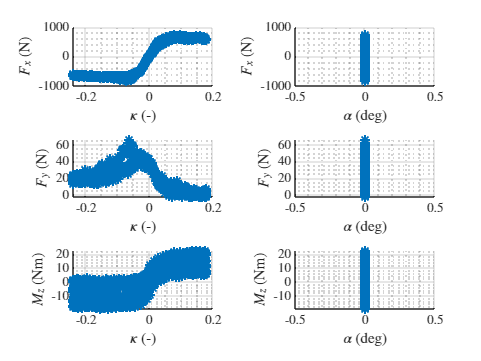





%% Intersect tables to obtain specific sub-datasets

[TData0, ~] = intersect_table_data( SA_0, GAMMA_0, FZ_220 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10 );
%[TDataSub, ~] = intersectTableData( ALPHA_00, GAMMA_00, VX_10, FZ_6500 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10, FZ_6500 );

% get data for tyre deflection (radius) versus speed
%[TDataSubRho, ~] = intersectTableData( KAPPA_00, ALPHA_00, GAMMA_00, FZ_6500 );


%% plot_selected_data

figure('Name','Selected-data')
plot_selected_data(TData0);

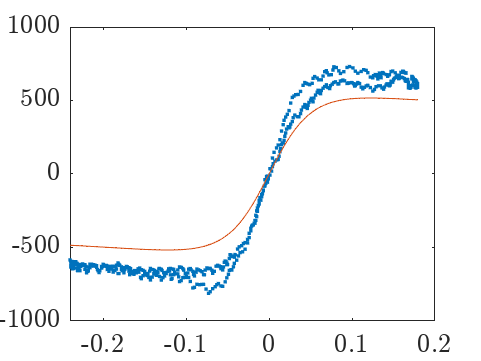


%% FITTING 
% initialise tyre data
tyre_coeffs = initialise_tyre_data(R0, Fz0);

%% Fitting with Fz=Fz_nom= 220N and camber=0  alpha = 0 VX= 10
% ------------------
% long slip

% Fit the coeffs {pCx1, pDx1, pEx1, pEx4, pKx1, pHx1, pVx1}
FZ0 = mean(TData0.FZ);

zeros_vec = zeros(size(TData0.SL));
ones_vec  = ones(size(TData0.SL));

FX0_guess = MF96_FX0_vec(TData0.SL,zeros_vec , zeros_vec, tyre_coeffs.FZ0*ones_vec, tyre_coeffs);

% check guess 
figure()
plot(TData0.SL,TData0.FX,'.')
hold on
plot(TData0.SL,FX0_guess,'-')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
P0 = [  1,   2,   1,  0,   0,   1,   0]; 

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
lb = [1,   0.1,   0,   0,  -10,    0,   -10];
ub = [2,    4,   1,   1,   10,   100,  10];


KAPPA_vec = TData0.SL;
FX_vec    = TData0.FX;

% check guess
SL_vec = -0.3:0.001:0.3;
FX0_fz_nom_vec = MF96_FX0_vec(SL_vec,zeros(size(SL_vec)) , zeros(size(SL_vec)), ...
                              FZ0.*ones(size(SL_vec)),tyre_coeffs);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_fz_nom_vec,'.')
% 


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_fz_nom,fval,exitflag] = fmincon(@(P)resid_pure_Fx(P,FX_vec, KAPPA_vec,0,FZ0, tyre_coeffs),...
                               P0,[],[],[],[],lb,ub);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


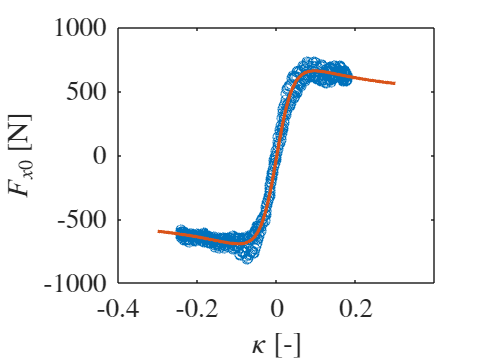


% Update tyre data with new optimal values                             
tyre_coeffs.pCx1 = P_fz_nom(1) ; % 1
tyre_coeffs.pDx1 = P_fz_nom(2) ;  
tyre_coeffs.pEx1 = P_fz_nom(3) ;
tyre_coeffs.pEx4 = P_fz_nom(4) ;
tyre_coeffs.pHx1 = P_fz_nom(5) ; 
tyre_coeffs.pKx1 = P_fz_nom(6) ;
tyre_coeffs.pVx1 = P_fz_nom(7) ;

FX0_fz_nom_vec = MF96_FX0_vec(SL_vec,zeros(size(SL_vec)) , zeros(size(SL_vec)), ...
                              FZ0.*ones(size(SL_vec)),tyre_coeffs);

figure('Name','Fx0(Fz0)')
plot(TData0.SL,TData0.FX,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(SL_vec,FX0_fz_nom_vec,'-','LineWidth',2)
xlabel('$\kappa$ [-]')
ylabel('$F_{x0}$ [N]')

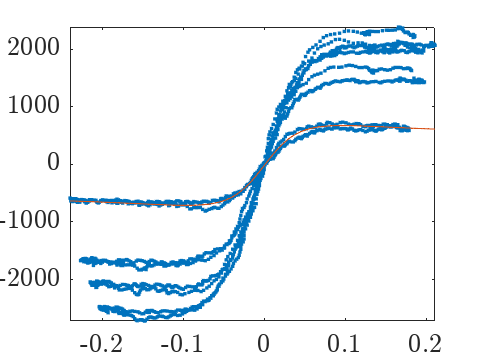


%% Fit coeefficient with variable load
% extract data with variable load
[TDataDFz, ~] = intersect_table_data( SA_0, GAMMA_0 );

% long slip

% Fit the coeffs {pCx1, pDx1, pEx1, pEx4, pKx1, pHx1, pVx1}
%FZ0 = mean(TData0.FZ);

zeros_vec = zeros(size(TDataDFz.SL));
ones_vec  = ones(size(TDataDFz.SL));

FX0_guess = MF96_FX0_vec(TDataDFz.SL,zeros_vec , zeros_vec, tyre_coeffs.FZ0*ones_vec, tyre_coeffs);

% check guess 
figure()
plot(TDataDFz.SL,TDataDFz.FX,'.')
hold on
plot(TDataDFz.SL,FX0_guess,'-')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
%    [pDx2 pEx2 pEx3 pHx2  pKx2  pKx3  pVx2] 
P0 = [  0,   0,   0,  0,   0,   0,   0]; 


% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
lb = [];
ub = [];


KAPPA_vec = TDataDFz.SL;
FX_vec    = TDataDFz.FX;
FZ_vec    = TDataDFz.FZ;

% check guess
SL_vec = -0.3:0.001:0.3;
FX0_dfz_vec = MF96_FX0_vec(SL_vec,zeros(size(SL_vec)) , zeros(size(SL_vec)), ...
                           TDataDFz.FZ,tyre_coeffs);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_dfz_vec,'.')


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_dfz,fval,exitflag] = fmincon(@(P)resid_pure_Fx_varFz(P,FX_vec, KAPPA_vec,0,FZ_vec, tyre_coeffs),...
                               P0,[],[],[],[],lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



disp(exitflag)

     1



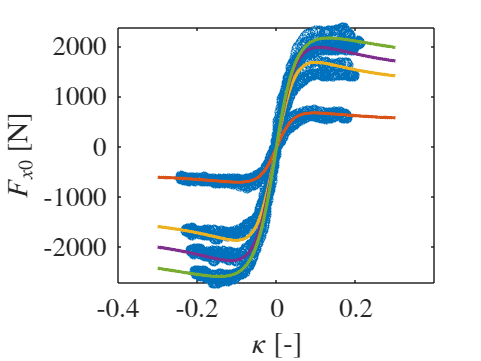

% Change tyre data with new optimal values                             
tyre_coeffs.pDx2 = P_dfz(1) ; % 1
tyre_coeffs.pEx2 = P_dfz(2) ;  
tyre_coeffs.pEx3 = P_dfz(3) ;
tyre_coeffs.pHx2 = P_dfz(4) ;
tyre_coeffs.pKx2 = P_dfz(5) ; 
tyre_coeffs.pKx3 = P_dfz(6) ;
tyre_coeffs.pVx2 = P_dfz(7) ;


res_FX0_dfz_vec = resid_pure_Fx_varFz(P_dfz,FX_vec,SL_vec,0 , FZ_vec,tyre_coeffs);

tmp_zeros = zeros(size(SL_vec));
tmp_ones = ones(size(SL_vec));


FX0_fz_var_vec1 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_220.FZ)*tmp_ones,tyre_coeffs);
FX0_fz_var_vec2 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_700.FZ)*tmp_ones,tyre_coeffs);
FX0_fz_var_vec3 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_900.FZ)*tmp_ones,tyre_coeffs);
FX0_fz_var_vec4 = MF96_FX0_vec(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_1120.FZ)*tmp_ones,tyre_coeffs);


figure('Name','Fx0(Fz0)')
plot(TDataDFz.SL,TDataDFz.FX,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
%plot(SL_vec,FX0_dfz_vec,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec1,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec2,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec3,'-','LineWidth',2)
plot(SL_vec,FX0_fz_var_vec4,'-','LineWidth',2)

xlabel('$\kappa$ [-]')
ylabel('$F_{x0}$ [N]')

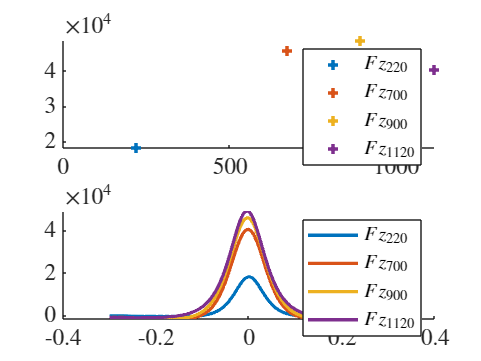



[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_220.FZ), tyre_coeffs);
Calfa_vec1_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);
[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_700.FZ), tyre_coeffs);
Calfa_vec2_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);
[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_900.FZ), tyre_coeffs);
Calfa_vec3_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);
[kappa__x, Bx, Cx, Dx, Ex, SVx] =MF96_FX0_coeffs(0, 0, 0, mean(FZ_1120.FZ), tyre_coeffs);
Calfa_vec4_0 = magic_formula_stiffness(kappa__x, Bx, Cx, Dx, Ex, SVx);

Calfa_vec1 = MF96_CorneringStiffness(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_220.FZ)*tmp_ones,tyre_coeffs);
Calfa_vec2 = MF96_CorneringStiffness(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_700.FZ)*tmp_ones,tyre_coeffs);
Calfa_vec3 = MF96_CorneringStiffness(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_900.FZ)*tmp_ones,tyre_coeffs);
Calfa_vec4 = MF96_CorneringStiffness(SL_vec,tmp_zeros ,tmp_zeros, mean(FZ_1120.FZ)*tmp_ones,tyre_coeffs);

figure('Name','C_alpha')
subplot(2,1,1)
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(mean(FZ_220.FZ),Calfa_vec1_0,'+','LineWidth',2)
plot(mean(FZ_700.FZ),Calfa_vec3_0,'+','LineWidth',2)
plot(mean(FZ_900.FZ),Calfa_vec4_0,'+','LineWidth',2)
plot(mean(FZ_1120.FZ),Calfa_vec2_0,'+','LineWidth',2)
legend({'$Fz_{220}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})

subplot(2,1,2)
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(SL_vec,Calfa_vec1,'-','LineWidth',2)
plot(SL_vec,Calfa_vec2,'-','LineWidth',2)
plot(SL_vec,Calfa_vec3,'-','LineWidth',2)
plot(SL_vec,Calfa_vec4,'-','LineWidth',2)
legend({'$Fz_{220}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})

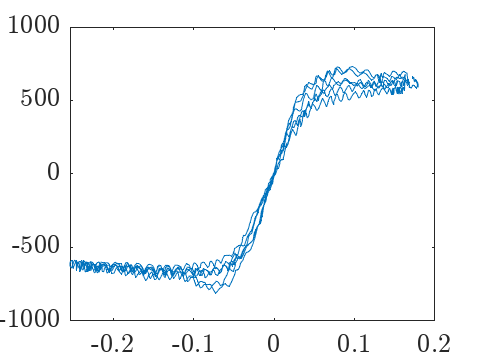



%% Fit coefficient with variable camber

% extract data with variable load
[TDataGamma, ~] = intersect_table_data( SA_0, FZ_220 );

% Fit the coeffs { pDx3}

% Guess values for parameters to be optimised
P0 = [0]; 

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%lb = [0, 0,  0, 0,  0,  0,  0];
%ub = [2, 1e6,1, 1,1e1,1e2,1e2];
lb = [];
ub = [];


zeros_vec = zeros(size(TDataGamma.SL));
ones_vec  = ones(size(TDataGamma.SL));

KAPPA_vec = TDataGamma.SL;
GAMMA_vec = TDataGamma.IA; 
FX_vec    = TDataGamma.FX;
FZ_vec    = TDataGamma.FZ;

figure()
plot(KAPPA_vec,FX_vec);



% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 
[P_varGamma,fval,exitflag] = fmincon(@(P)resid_pure_Fx_varGamma(P,FX_vec, KAPPA_vec,GAMMA_vec,tyre_coeffs.FZ0, tyre_coeffs),...
                               P0,[],[],[],[],lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


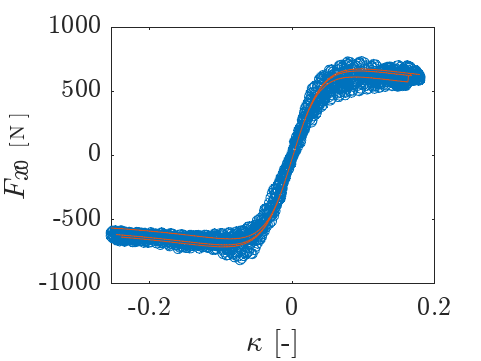


% Change tyre data with new optimal values                             
tyre_coeffs.pDx3 = P_varGamma(1) ; % 1

FX0_varGamma_vec = MF96_FX0_vec(KAPPA_vec,zeros_vec , GAMMA_vec, tyre_coeffs.FZ0*ones_vec,tyre_coeffs);

figure('Name','Fx0 vs Gamma')
plot(KAPPA_vec,TDataGamma.FX,'o')
hold on
plot(KAPPA_vec,FX0_varGamma_vec,'-')
xlabel('$\kappa$ [-]')
ylabel('$F_{x0}$ [N]')

% Calculate the residuals with the optimal solution found above
res_Fx0_varGamma  = resid_pure_Fx_varGamma(P_varGamma,FX_vec, KAPPA_vec,GAMMA_vec,tyre_coeffs.FZ0, tyre_coeffs);

% R-squared is 
% 1-SSE/SST
% SSE/SST = res_Fx0_nom

% SSE is the sum of squared error,  SST is the sum of squared total
fprintf('R-squared = %6.3f\n',1-res_Fx0_varGamma);

R-squared =  0.994




[kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, GAMMA_vec(3), tyre_coeffs.FZ0, tyre_coeffs);
% 
fprintf('Bx      = %6.3f\n',Bx);

Bx      = 17.021


fprintf('Cx      = %6.3f\n',Cx);

Cx      =  1.539


fprintf('mux      = %6.3f\n',Dx/tyre_coeffs.FZ0);

mux      =  3.147


fprintf('Ex      = %6.3f\n',Ex);

Ex      =  0.011


fprintf('SVx     = %6.3f\n',SVx);

SVx     = -18.871


fprintf('kappa_x = %6.3f\n',kappa__x);

kappa_x = -0.000


fprintf('Kx      = %6.3f\n',Bx*Cx*Dx/tyre_coeffs.FZ0);

Kx      = 82.417



% % Longitudinal stiffness
% Kx_vec = zeros(size(load_vec));
% for i = 1:length(load_vec)
%   [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, 0, load_vec(i), tyre_data);
%   Kx_vec(i) = Bx*Cx*Dx/tyre_data.Fz0;
% end
% 
% figure('Name','Kx vs Fz')
% plot(load_vec,Kx_vec,'o-')

%% Save tyre data structure to mat file
%
save(['tyre_' data_set,'.mat'],'tyre_coeffs');




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




%% Select tyre dataset - PURE LATERAL
%dataset path
data_set_path = 'dataset/';
% dataset selection and loading

data_set = 'Hoosier_B1464run23'; % pure lateral forces
%data_set = 'Hoosier_B1464run30';  % braking/traction (pure log. force) + combined

% tyre geometric data:
% Hoosier 20.5x7.0 - 13 R25B
% 13 diameter in inches
% 7.0 section width in inches
% tread width in inches
diameter = 13*2.56; %
Fz0 = 220;   % [N] nominal load is given
R0  = diameter/2/100; % [m] get from nominal load R0 (m) *** TO BE CHANGED ***


fprintf('Loading dataset ...')

Loading dataset ...

switch data_set
  case 'Hoosier_B1464run23'
  load ([data_set_path, 'Hoosier_B1464run23.mat']); % pure lateral
  cut_start = 27760;
  cut_end   = 54500;
  case 'Hoosier_B1464run30'
  load ([data_set_path, 'Hoosier_B1464run30.mat']); % pure longitudinal
  cut_start = 19028;
  cut_end   = 37643;
  otherwise 
  error('Not found dataset: `%s`\n', data_set) ;
  
end

% select dataset portion
smpl_range = cut_start:cut_end;

fprintf('completed!\n')

completed!


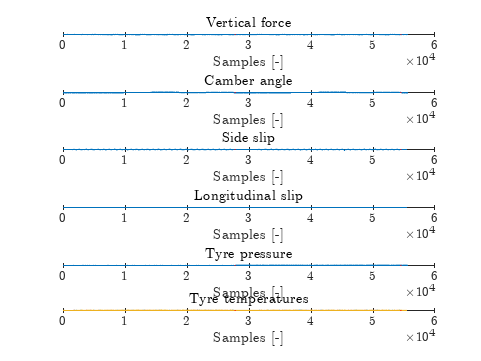


%% Plot raw data

figure
tiledlayout(6,1)

ax_list(1) = nexttile; y_range = [min(min(-FZ),0) round(max(-FZ)*1.1)];
plot(-FZ)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list(2) = nexttile; y_range = [min(min(IA),0) round(max(IA)*1.1)];
plot(IA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(3) = nexttile; y_range = [min(min(SA),0) round(max(SA)*1.1)];
plot(SA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Side slip')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(4) = nexttile; y_range = [min(min(SL),0) round(max(SL)*1.1)];
plot(SL)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Longitudinal slip')
xlabel('Samples [-]')
ylabel('[-]')

ax_list(5) = nexttile; y_range = [min(min(P),0) round(max(P)*1.1)];
plot(P)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre pressure')
xlabel('Samples [-]')
ylabel('[Pa]')

ax_list(6) = nexttile;  y_range = [min(min(TSTC),0) round(max(TSTC)*1.1)];
plot(TSTC,'DisplayName','Center')
hold on
plot(TSTI,'DisplayName','Internal')
plot(TSTO,'DisplayName','Outboard')
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre temperatures')
xlabel('Samples [-]')
ylabel('[degC]')

linkaxes(ax_list,'x')

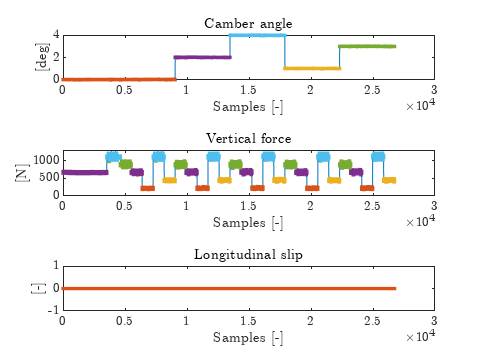



%plot(SA,FY)


%% Select some specific data
% Cut crappy data and select only 12 psi data

vec_samples = 1:1:length(smpl_range);
tyre_data = table(); % create empty table
% store raw data in table
tyre_data.SL =  SL(smpl_range);
tyre_data.SA = -SA(smpl_range)*to_rad;
tyre_data.FZ = -FZ(smpl_range);  % 0.453592  lb/kg
tyre_data.FX =  FX(smpl_range);
tyre_data.FY =  FY(smpl_range);
tyre_data.MZ =  MZ(smpl_range);
tyre_data.IA =  IA(smpl_range)*to_rad;

% Extract points at constant inclination angle
GAMMA_tol = 0.05*to_rad;
idx.GAMMA_0 = 0.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 0.0*to_rad+GAMMA_tol;
idx.GAMMA_1 = 1.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 1.0*to_rad+GAMMA_tol;
idx.GAMMA_2 = 2.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 2.0*to_rad+GAMMA_tol;
idx.GAMMA_3 = 3.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 3.0*to_rad+GAMMA_tol;
idx.GAMMA_4 = 4.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 4.0*to_rad+GAMMA_tol;
idx.GAMMA_5 = 5.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 5.0*to_rad+GAMMA_tol;
GAMMA_0  = tyre_data( idx.GAMMA_0, : );
GAMMA_1  = tyre_data( idx.GAMMA_1, : );
GAMMA_2  = tyre_data( idx.GAMMA_2, : );
GAMMA_3  = tyre_data( idx.GAMMA_3, : );
GAMMA_4  = tyre_data( idx.GAMMA_4, : );
GAMMA_5  = tyre_data( idx.GAMMA_5, : );

% Extract points at constant vertical load
% Test data done at: 
%  - 50lbf  ( 50*0.453592*9.81 =  223N )
%  - 150lbf (150*0.453592*9.81 =  667N )
%  - 200lbf (200*0.453592*9.81 =  890N )
%  - 250lbf (250*0.453592*9.81 = 1120N )

FZ_tol = 100;
idx.FZ_220  = 220-FZ_tol < tyre_data.FZ & tyre_data.FZ < 220+FZ_tol;
idx.FZ_440  = 440-FZ_tol < tyre_data.FZ & tyre_data.FZ < 440+FZ_tol;
idx.FZ_700  = 700-FZ_tol < tyre_data.FZ & tyre_data.FZ < 700+FZ_tol;
idx.FZ_900  = 900-FZ_tol < tyre_data.FZ & tyre_data.FZ < 900+FZ_tol;
idx.FZ_1120 = 1120-FZ_tol < tyre_data.FZ & tyre_data.FZ < 1120+FZ_tol;
FZ_220  = tyre_data( idx.FZ_220, : );
FZ_440  = tyre_data( idx.FZ_440, : );
FZ_700  = tyre_data( idx.FZ_700, : );
FZ_900  = tyre_data( idx.FZ_900, : );
FZ_1120 = tyre_data( idx.FZ_1120, : );

% The slip angle is varied continuously between -4 and +12° and then
% between -12° and +4° for the pure slip case

SL_tol = 0.01;
idx.SL_0    =  0-SL_tol          < tyre_data.SL & tyre_data.SL < 0+SL_tol;
SL_0     = tyre_data( idx.SL_0, : );

figure()
tiledlayout(3,1)

ax_list(1) = nexttile;
plot(tyre_data.IA*to_deg)
hold on
plot(vec_samples(idx.GAMMA_0),GAMMA_0.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_1),GAMMA_1.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_2),GAMMA_2.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_3),GAMMA_3.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_4),GAMMA_4.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_5),GAMMA_5.IA*to_deg,'.');
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(2) = nexttile;
plot(tyre_data.FZ)
hold on
plot(vec_samples(idx.FZ_220),FZ_220.FZ,'.');
plot(vec_samples(idx.FZ_440),FZ_440.FZ,'.');
plot(vec_samples(idx.FZ_700),FZ_700.FZ,'.');
plot(vec_samples(idx.FZ_900),FZ_900.FZ,'.');
plot(vec_samples(idx.FZ_1120),FZ_1120.FZ,'.');
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list(3) = nexttile;
plot(tyre_data.SL)
hold on
plot(vec_samples(idx.SL_0),   SL_0.SL,'.');
title('Longitudinal slip')
xlabel('Samples [-]')
ylabel('[-]')

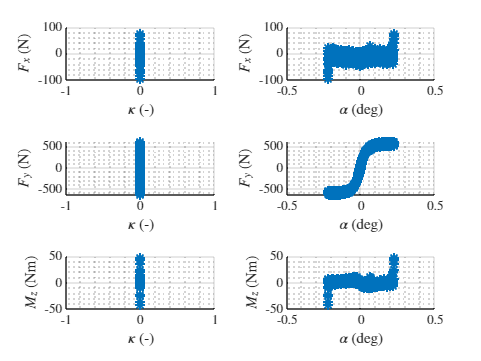





%% Intersect tables to obtain specific sub-datasets

[TData0_pl, ~] = intersect_table_data( SL_0, GAMMA_0, FZ_220 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10 );
%[TDataSub, ~] = intersectTableData( ALPHA_00, GAMMA_00, VX_10, FZ_6500 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10, FZ_6500 );

% get data for tyre deflection (radius) versus speed
%[TDataSubRho, ~] = intersectTableData( KAPPA_00, ALPHA_00, GAMMA_00, FZ_6500 );


%% plot_selected_data

figure('Name','Selected-data')
plot_selected_data(TData0_pl);

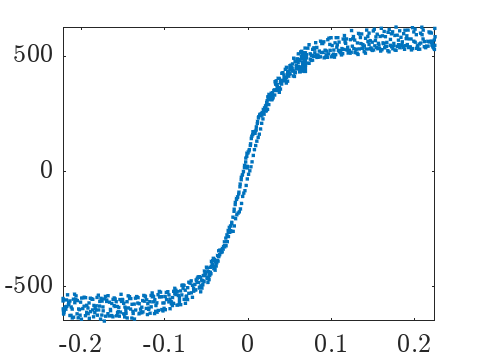



%% FITTING - PURE LATERAL
% initialise tyre data
tyre_coeffs_pl = initialise_tyre_data(R0, Fz0);

%% Fitting with Fz=Fz_nom= 220N and camber=0  k = 0 VX= 10
% ------------------
% lateral slip

% Fit the coeffs {pCx1, pDx1, pEx1, pEx4, pKx1, pHx1, pVx1}
FZ0 = mean(TData0_pl.FZ);

zeros_vec = zeros(size(TData0_pl.SA));
ones_vec  = ones(size(TData0_pl.SA));

FY0_guess = MF96_FY0_vec(zeros_vec, TData0_pl.SA, zeros_vec, tyre_coeffs_pl.FZ0*ones_vec, tyre_coeffs_pl);

% check guess 
figure()
plot(TData0_pl.SA,TData0_pl.FY,'.')
hold on
plot(TData0_pl.SA,FY0_guess,'-')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
%    [pCy1 pDy1 pEy1 pHy1  pKy1  pKy2  pVy1 
P0_pl = [  1,   1,   1,  1,   1,   1,   1]; 

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
% lb = [1,   0.1,   0,   0,  -10,    0,   -10];
% ub = [2,    4,   1,   1,   10,   100,  10];


ALPHA_vec = TData0_pl.SA;
FY_vec    = TData0_pl.FY;

% check guess
SA_vec = -12*to_rad:0.001:12*to_rad;
FY0_fz_nom_vec = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec, zeros(size(SA_vec)), ...
                              FZ0.*ones(size(SA_vec)),tyre_coeffs_pl);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_fz_nom_vec,'.')
% 


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_fz_nom,fval,exitflag] = fmincon(@(P)resid_pure_Fy(P,FY_vec, ALPHA_vec,0, FZ0, tyre_coeffs_pl),...
                               P0_pl,[],[],[],[],[],[]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


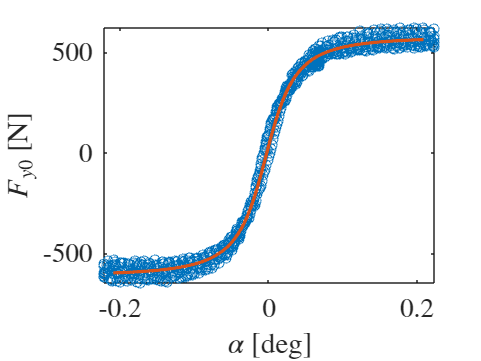


% Update tyre data with new optimal values                             
tyre_coeffs_pl.pCy1 = P_fz_nom(1); 
tyre_coeffs_pl.pDy1 = P_fz_nom(2);
tyre_coeffs_pl.pEy1 = P_fz_nom(3);
tyre_coeffs_pl.pHy1 = P_fz_nom(4);
tyre_coeffs_pl.pKy1 = P_fz_nom(5);
tyre_coeffs_pl.pKy2 = P_fz_nom(6);
tyre_coeffs_pl.pVy1 = P_fz_nom(7);

FY0_fz_nom_vec = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec, zeros(size(SA_vec)), ...
                              FZ0.*ones(size(SA_vec)),tyre_coeffs_pl);

figure('Name','Fy0(Fz0)')
plot(TData0_pl.SA,TData0_pl.FY,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(SA_vec,FY0_fz_nom_vec,'-','LineWidth',2)
xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}$ [N]')

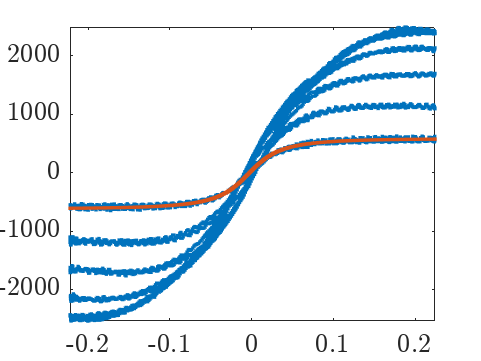


%% Fit coeefficient with variable load
% extract data with variable load
[TDataDFz, ~] = intersect_table_data( SL_0, GAMMA_0 );
% lateral slip

% Fit the coeffs {pCx1, pDx1, pEx1, pEx4, pKx1, pHx1, pVx1}
%FZ0 = mean(TData0.FZ);

zeros_vec = zeros(size(TDataDFz.SA));
ones_vec  = ones(size(TDataDFz.SA));

FY0_guess = MF96_FY0_vec(zeros_vec, TDataDFz.SA, zeros_vec, tyre_coeffs_pl.FZ0*ones_vec, tyre_coeffs_pl);

% check guess 
figure()
plot(TDataDFz.SA,TDataDFz.FY,'.')
hold on
plot(TDataDFz.SA,FY0_guess,'.')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
% Guess values for parameters to be optimised
% [pDy2 pEy2 pHy2 pVy2] 
P0_pl_dFz = [ 0 , 0 , 0 , 0 ]; 


% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
lb = [];
ub = [];


ALPHA_vec = TDataDFz.SA;
FY_vec    = TDataDFz.FY;
FZ_vec    = TDataDFz.FZ;

% check guess
SA_vec = -12*to_rad:0.001:12*to_rad;
FY0_dfz_vec = MF96_FY0_vec(zeros(size(SA_vec)),  SA_vec, zeros(size(SA_vec)), ...
                           FZ_vec, tyre_coeffs_pl);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_dfz_vec,'.')


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_dfz_pl,fval,exitflag] = fmincon(@(P)resid_pure_Fy_varFz(P,FY_vec, ALPHA_vec, 0, FZ_vec, tyre_coeffs_pl),...
                               P0_pl_dFz,[],[],[],[],lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



disp(exitflag)

     1



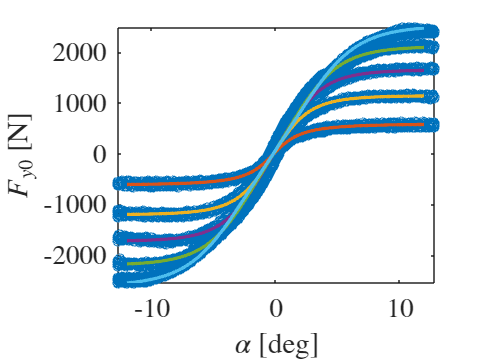

% Change tyre data with new optimal values                             
tyre_coeffs_pl.pDy2 = P_dfz_pl(1) ; % 1
tyre_coeffs_pl.pEy2 = P_dfz_pl(2) ;  
tyre_coeffs_pl.pHy2 = P_dfz_pl(3) ;
tyre_coeffs_pl.pVy2 = P_dfz_pl(4) ;


res_FY0_dfz_vec = resid_pure_Fy_varFz(P_dfz_pl,FY_vec, SA_vec, 0 , FZ_vec,tyre_coeffs_pl);

tmp_zeros = zeros(size(SA_vec));
tmp_ones = ones(size(SA_vec));


FY0_fz_var_vec1 = MF96_FY0_vec(tmp_zeros, SA_vec, tmp_zeros, mean(FZ_220.FZ)*tmp_ones,tyre_coeffs_pl);
FY0_fz_var_vec2 = MF96_FY0_vec(tmp_zeros, SA_vec, tmp_zeros, mean(FZ_440.FZ)*tmp_ones,tyre_coeffs_pl);
FY0_fz_var_vec3 = MF96_FY0_vec(tmp_zeros, SA_vec, tmp_zeros, mean(FZ_700.FZ)*tmp_ones,tyre_coeffs_pl);
FY0_fz_var_vec4 = MF96_FY0_vec(tmp_zeros, SA_vec, tmp_zeros, mean(FZ_900.FZ)*tmp_ones,tyre_coeffs_pl);
FY0_fz_var_vec5 = MF96_FY0_vec(tmp_zeros, SA_vec, tmp_zeros, mean(FZ_1120.FZ)*tmp_ones,tyre_coeffs_pl);


figure('Name','Fy0(Fz0)')
plot(TDataDFz.SA*to_deg,TDataDFz.FY,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
%plot(SL_vec,FX0_dfz_vec,'-','LineWidth',2)
plot(SA_vec*to_deg,FY0_fz_var_vec1,'-','LineWidth',2)
plot(SA_vec*to_deg,FY0_fz_var_vec2,'-','LineWidth',2)
plot(SA_vec*to_deg,FY0_fz_var_vec3,'-','LineWidth',2)
plot(SA_vec*to_deg,FY0_fz_var_vec4,'-','LineWidth',2)
plot(SA_vec*to_deg,FY0_fz_var_vec5,'-','LineWidth',2)

xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}$ [N]')

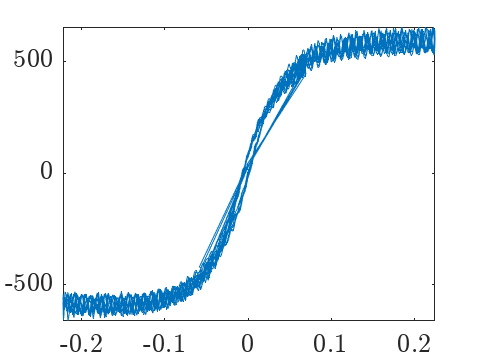



% [alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_220.FZ), tyre_coeffs);
% Calfa_vec1_0 = Kya;
% [alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_440.FZ), tyre_coeffs);
% Calfa_vec2_0 = Kya;
% [alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_700.FZ), tyre_coeffs);
% Calfa_vec3_0 = Kya;
% [alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_900.FZ), tyre_coeffs);
% Calfa_vec4_0 = Kya;
% [alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_1120.FZ), tyre_coeffs);
% Calfa_vec5_0 = Kya;
% % 
% Calfa_vec1 = MF96_CorneringStiffness(SA_vec,tmp_zeros ,tmp_zeros, mean(FZ_220.FZ)*tmp_ones,tyre_coeffs);
% Calfa_vec2 = MF96_CorneringStiffness(SA_vec,tmp_zeros ,tmp_zeros, mean(FZ_440.FZ)*tmp_ones,tyre_coeffs);
% Calfa_vec3 = MF96_CorneringStiffness(SA_vec,tmp_zeros ,tmp_zeros, mean(FZ_700.FZ)*tmp_ones,tyre_coeffs);
% Calfa_vec4 = MF96_CorneringStiffness(SA_vec,tmp_zeros ,tmp_zeros, mean(FZ_900.FZ)*tmp_ones,tyre_coeffs);
% Calfa_vec5 = MF96_CorneringStiffness(SA_vec,tmp_zeros ,tmp_zeros, mean(FZ_1120.FZ)*tmp_ones,tyre_coeffs);
% 
% figure('Name','C_alpha')
% subplot(2,1,1)
% hold on
% %plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
% plot(mean(FZ_220.FZ),Calfa_vec1_0,'+','LineWidth',2)
% plot(mean(FZ_440.FZ),Calfa_vec2_0,'+','LineWidth',2)
% plot(mean(FZ_700.FZ),Calfa_vec3_0,'+','LineWidth',2)
% plot(mean(FZ_900.FZ),Calfa_vec4_0,'+','LineWidth',2)
% plot(mean(FZ_1120.FZ),Calfa_vec5_0,'+','LineWidth',2)
% legend({'$Fz_{220}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})

% subplot(2,1,2)
% hold on
% %plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
% plot(SL_vec,Calfa_vec1,'-','LineWidth',2)
% plot(SL_vec,Calfa_vec2,'-','LineWidth',2)
% plot(SL_vec,Calfa_vec3,'-','LineWidth',2)
% plot(SL_vec,Calfa_vec4,'-','LineWidth',2)
% legend({'$Fz_{220}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Fit coefficient with variable camber


SA_tol = 0.5*to_rad;
idx.SA_0    =  0-SA_tol          < tyre_data.SA & tyre_data.SA < 0+SA_tol;
idx.SA_3neg = -(3*to_rad+SA_tol) < tyre_data.SA & tyre_data.SA < -3*to_rad+SA_tol;
idx.SA_6neg = -(6*to_rad+SA_tol) < tyre_data.SA & tyre_data.SA < -6*to_rad+SA_tol;
SA_0_LAT     = tyre_data( idx.SA_0, : );

% extract data with variable load
[TDataGamma, ~] = intersect_table_data(SL_0, FZ_220);

% Extract points at constant camber and plot
GAMMA_tol_pl_dgamma = 0.05*to_rad;
idx_pl_dgamma.GAMMA_0 = 0.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma.IA & TDataGamma.IA < 0.0*to_rad+GAMMA_tol_pl_dgamma;
idx_pl_dgamma.GAMMA_1 = 1.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma.IA & TDataGamma.IA < 1.0*to_rad+GAMMA_tol_pl_dgamma;
idx_pl_dgamma.GAMMA_2 = 2.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma.IA & TDataGamma.IA < 2.0*to_rad+GAMMA_tol_pl_dgamma;
idx_pl_dgamma.GAMMA_3 = 3.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma.IA & TDataGamma.IA < 3.0*to_rad+GAMMA_tol_pl_dgamma;
idx_pl_dgamma.GAMMA_4 = 4.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma.IA & TDataGamma.IA < 4.0*to_rad+GAMMA_tol_pl_dgamma;

GAMMA_0_dgamma  = TDataGamma( idx_pl_dgamma.GAMMA_0, : );
GAMMA_1_dgamma  = TDataGamma( idx_pl_dgamma.GAMMA_1, : );
GAMMA_2_dgamma  = TDataGamma( idx_pl_dgamma.GAMMA_2, : );
GAMMA_3_dgamma  = TDataGamma( idx_pl_dgamma.GAMMA_3, : );
GAMMA_4_dgamma  = TDataGamma( idx_pl_dgamma.GAMMA_4, : );


% Fit the coeffs { pDy3, pEy3, pEy4, pHy3, pKy3, pVy3, pVy4 }
% Guess values for parameters to be optimised
P0_gamma = [0.51e1, 1.88, -0.42e1, -2.04, 0.13e1, -0.29e1, -0.28e1];

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%lb = [0, 0,  0, 0,  0,  0,  0];
%ub = [2, 1e6,1, 1,1e1,1e2,1e2];
lb = [5,1,-100,-2.5,0,-100,-100];
ub = [100,100,0,-0.1,100,0,0];

%NB -> cambiato pHy3 con -2.043155252823728 uscito dall'analisi con side
%slip = 0 intersecato con FZ_220. Pesa molto l'upper bound al quale cerca
%di avvicinarsi il più possibile, più è grande in modulo, più si allargano
%tra loro le curve al centro. alternativa allo 0.1 è 0.15 dove si allargano
%leggermente di più. agli estremi rimangono pressochè uguali e attaccate

zeros_vec = zeros(size(TDataGamma.IA));
ones_vec  = ones(size(TDataGamma.IA));

ALPHA_vec = TDataGamma.SA;
GAMMA_vec = TDataGamma.IA; 
FY_vec    = TDataGamma.FY;
FZ_vec    = TDataGamma.FZ;

figure()
plot(ALPHA_vec,FY_vec);



% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 
[P_varGamma,fval,exitflag] = fmincon(@(P)resid_pure_Fy_varGamma(P,FY_vec, ALPHA_vec,GAMMA_vec,tyre_coeffs.FZ0, tyre_coeffs_pl),...
                               P0_gamma,[],[],[],[],lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


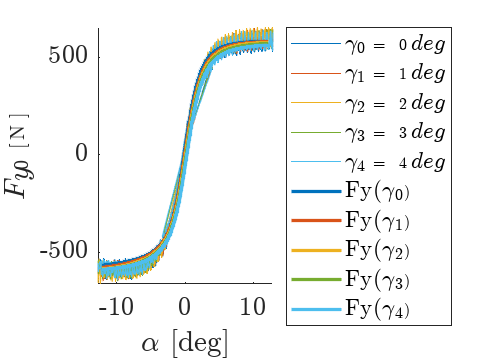


% Change tyre data with new optimal values                             
tyre_coeffs_pl.pDy3 = P_varGamma(1); % 1
tyre_coeffs_pl.pEy3 = P_varGamma(2); 
tyre_coeffs_pl.pEy4 = P_varGamma(3);
tyre_coeffs_pl.pHy3 = P_varGamma(4); 
tyre_coeffs_pl.pKy3 = P_varGamma(5); 
tyre_coeffs_pl.pVy3 = P_varGamma(6); 
tyre_coeffs_pl.pVy4 = P_varGamma(7); 

% FY0_varGamma_vec = MF96_FY0_vec(zeros_vec, ALPHA_vec, GAMMA_vec, tyre_coeffs_pl.FZ0*ones_vec,tyre_coeffs_pl);
% 
% figure('Name','Fy0 vs Gamma')
% plot(ALPHA_vec*to_deg,TDataGamma.FY,'o')
% hold on
% plot(ALPHA_vec*to_deg,FY0_varGamma_vec,'.')
% xlabel('$\alpha$ [deg]')
% ylabel('$F_{y0}$ [N]')

FY0_gamma_var_vec1 = MF96_FY0_vec(zeros_vec, SA_vec ,mean(GAMMA_0_dgamma.IA)*ones_vec, mean(TDataGamma.FZ)*ones_vec,tyre_coeffs_pl);
FY0_gamma_var_vec2 = MF96_FY0_vec(zeros_vec, SA_vec ,mean(GAMMA_1_dgamma.IA)*ones_vec, mean(TDataGamma.FZ)*ones_vec,tyre_coeffs_pl);
FY0_gamma_var_vec3 = MF96_FY0_vec(zeros_vec, SA_vec ,mean(GAMMA_2_dgamma.IA)*ones_vec, mean(TDataGamma.FZ)*ones_vec,tyre_coeffs_pl);
FY0_gamma_var_vec4 = MF96_FY0_vec(zeros_vec, SA_vec ,mean(GAMMA_3_dgamma.IA)*ones_vec, mean(TDataGamma.FZ)*ones_vec,tyre_coeffs_pl);
FY0_gamma_var_vec5 = MF96_FY0_vec(zeros_vec, SA_vec ,mean(GAMMA_4_dgamma.IA)*ones_vec, mean(TDataGamma.FZ)*ones_vec,tyre_coeffs_pl);


figure()
hold on
plot(GAMMA_0_dgamma.SA*to_deg,GAMMA_0_dgamma.FY,'-','MarkerSize',5, 'Color', '#0072BD') %'MarkerEdgeColor','y',
plot(GAMMA_1_dgamma.SA*to_deg,GAMMA_1_dgamma.FY,'-','MarkerSize',5, 'Color', '#D95319') %'MarkerEdgeColor','c',
plot(GAMMA_2_dgamma.SA*to_deg,GAMMA_2_dgamma.FY,'-','MarkerSize',5, 'Color', '#EDB120') %'MarkerEdgeColor','m',
plot(GAMMA_3_dgamma.SA*to_deg,GAMMA_3_dgamma.FY,'-','MarkerSize',5, 'Color', '#77AC30') %'MarkerEdgeColor','b',
plot(GAMMA_4_dgamma.SA*to_deg,GAMMA_4_dgamma.FY,'-','MarkerSize',5, 'Color', '#4DBEEE') %'MarkerEdgeColor','r',
plot(SA_vec*to_deg,FY0_gamma_var_vec1,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#0072BD')
plot(SA_vec*to_deg,FY0_gamma_var_vec2,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#D95319')
plot(SA_vec*to_deg,FY0_gamma_var_vec3,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#EDB120')
plot(SA_vec*to_deg,FY0_gamma_var_vec4,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#77AC30')
plot(SA_vec*to_deg,FY0_gamma_var_vec5,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#4DBEEE')
legend({'$ \gamma_0 = 0 deg $','$ \gamma_1 = 1 deg $','$ \gamma_2 = 2 deg $','$ \gamma_3 = 3 deg$','$ \gamma_4 = 4 deg $', 'Fy($\gamma_0$)','Fy($\gamma_1$)','Fy($\gamma_2$)','Fy($\gamma_3$)','Fy($\gamma_4$)'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}$ [N]')



% Calculate the residuals with the optimal solution found above
res_Fy0_varGamma  = resid_pure_Fy_varGamma(P_varGamma,FY_vec, ALPHA_vec, GAMMA_vec, tyre_coeffs_pl.FZ0, tyre_coeffs_pl);

% % R-squared is 
% % 1-SSE/SST
% % SSE/SST = res_Fx0_nom
% 
% % SSE is the sum of squared error,  SST is the sum of squared total
% fprintf('R-squared = %6.3f\n',1-res_Fx0_varGamma);
% 
% 
% [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, GAMMA_vec(3), tyre_coeffs.FZ0, tyre_coeffs);
% % 
% fprintf('Bx      = %6.3f\n',Bx);
% fprintf('Cx      = %6.3f\n',Cx);
% fprintf('mux      = %6.3f\n',Dx/tyre_coeffs.FZ0);
% fprintf('Ex      = %6.3f\n',Ex);
% fprintf('SVx     = %6.3f\n',SVx);
% fprintf('kappa_x = %6.3f\n',kappa__x);
% fprintf('Kx      = %6.3f\n',Bx*Cx*Dx/tyre_coeffs.FZ0);

% % Longitudinal stiffness
% Kx_vec = zeros(size(load_vec));
% for i = 1:length(load_vec)
%   [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, 0, load_vec(i), tyre_data);
%   Kx_vec(i) = Bx*Cx*Dx/tyre_data.Fz0;
% end
% 
% figure('Name','Kx vs Fz')
% plot(load_vec,Kx_vec,'o-')

%% Save tyre data structure to mat file
%
save(['tyre_' data_set,'.mat'],'tyre_coeffs_pl');



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%% Select tyre dataset - PURE SELF ALIGNING MOMENT
%dataset path
data_set_path = 'dataset/';
% dataset selection and loading

data_set = 'Hoosier_B1464run23'; % pure lateral forces
%data_set = 'Hoosier_B1464run30';  % braking/traction (pure log. force) + combined

% tyre geometric data:
% Hoosier 20.5x7.0 - 13 R25B
% 13 diameter in inches
% 7.0 section width in inches
% tread width in inches
diameter = 13*2.56; %
Fz0 = 220;   % [N] nominal load is given
R0  = diameter/2/100; % [m] get from nominal load R0 (m) *** TO BE CHANGED ***


fprintf('Loading dataset ...')

Loading dataset ...

switch data_set
  case 'Hoosier_B1464run23'
  load ([data_set_path, 'Hoosier_B1464run23.mat']); % pure lateral
  cut_start = 27760;
  cut_end   = 54500;
  case 'Hoosier_B1464run30'
  load ([data_set_path, 'Hoosier_B1464run30.mat']); % pure longitudinal
  cut_start = 19028;
  cut_end   = 37643;
  otherwise 
  error('Not found dataset: `%s`\n', data_set) ;
  
end

% select dataset portion
smpl_range = cut_start:cut_end;

fprintf('completed!\n')

completed!


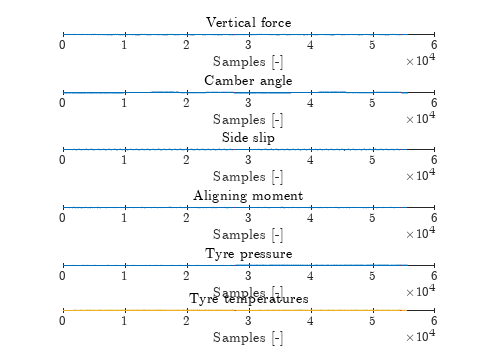


%% Plot raw data

figure
tiledlayout(6,1)

ax_list(1) = nexttile; y_range = [min(min(-FZ),0) round(max(-FZ)*1.1)];
plot(-FZ)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list(2) = nexttile; y_range = [min(min(IA),0) round(max(IA)*1.1)];
plot(IA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(3) = nexttile; y_range = [min(min(SA),0) round(max(SA)*1.1)];
plot(SA)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Side slip')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(4) = nexttile; y_range = [min(min(MZ),0) round(max(MZ)*1.1)];
plot(MZ)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Aligning moment')
xlabel('Samples [-]')
ylabel('[Nm]')

ax_list(5) = nexttile; y_range = [min(min(P),0) round(max(P)*1.1)];
plot(P)
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre pressure')
xlabel('Samples [-]')
ylabel('[Pa]')

ax_list(6) = nexttile;  y_range = [min(min(TSTC),0) round(max(TSTC)*1.1)];
plot(TSTC,'DisplayName','Center')
hold on
plot(TSTI,'DisplayName','Internal')
plot(TSTO,'DisplayName','Outboard')
hold on
plot([cut_start cut_start],y_range,'--r')
plot([cut_end cut_end],y_range,'--r')
title('Tyre temperatures')
xlabel('Samples [-]')
ylabel('[degC]')



linkaxes(ax_list,'x')



%plot(SA,FY)


%% Select some specific data
% Cut crappy data and select only 12 psi data

vec_samples = 1:1:length(smpl_range);
tyre_data = table(); % create empty table
% store raw data in table
tyre_data.SL =  SL(smpl_range);
tyre_data.SA = -SA(smpl_range)*to_rad;
tyre_data.FZ = -FZ(smpl_range);  % 0.453592  lb/kg
tyre_data.FX =  FX(smpl_range);
tyre_data.FY =  FY(smpl_range);
tyre_data.MZ =  MZ(smpl_range);
tyre_data.IA =  IA(smpl_range)*to_rad;

% Extract points at constant inclination angle
GAMMA_tol = 0.05*to_rad;
idx.GAMMA_0 = 0.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 0.0*to_rad+GAMMA_tol;
idx.GAMMA_1 = 1.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 1.0*to_rad+GAMMA_tol;
idx.GAMMA_2 = 2.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 2.0*to_rad+GAMMA_tol;
idx.GAMMA_3 = 3.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 3.0*to_rad+GAMMA_tol;
idx.GAMMA_4 = 4.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 4.0*to_rad+GAMMA_tol;
idx.GAMMA_5 = 5.0*to_rad-GAMMA_tol < tyre_data.IA & tyre_data.IA < 5.0*to_rad+GAMMA_tol;
GAMMA_0  = tyre_data( idx.GAMMA_0, : );
GAMMA_1  = tyre_data( idx.GAMMA_1, : );
GAMMA_2  = tyre_data( idx.GAMMA_2, : );
GAMMA_3  = tyre_data( idx.GAMMA_3, : );
GAMMA_4  = tyre_data( idx.GAMMA_4, : );
GAMMA_5  = tyre_data( idx.GAMMA_5, : );

% Extract points at constant vertical load
% Test data done at: 
%  - 50lbf  ( 50*0.453592*9.81 =  223N )
%  - 150lbf (150*0.453592*9.81 =  667N )
%  - 200lbf (200*0.453592*9.81 =  890N )
%  - 250lbf (250*0.453592*9.81 = 1120N )

FZ_tol = 100;
idx.FZ_220  = 220-FZ_tol < tyre_data.FZ & tyre_data.FZ < 220+FZ_tol;
idx.FZ_440  = 440-FZ_tol < tyre_data.FZ & tyre_data.FZ < 440+FZ_tol;
idx.FZ_700  = 700-FZ_tol < tyre_data.FZ & tyre_data.FZ < 700+FZ_tol;
idx.FZ_900  = 900-FZ_tol < tyre_data.FZ & tyre_data.FZ < 900+FZ_tol;
idx.FZ_1120 = 1120-FZ_tol < tyre_data.FZ & tyre_data.FZ < 1120+FZ_tol;
FZ_220  = tyre_data( idx.FZ_220, : );
FZ_440  = tyre_data( idx.FZ_440, : );
FZ_700  = tyre_data( idx.FZ_700, : );
FZ_900  = tyre_data( idx.FZ_900, : );
FZ_1120 = tyre_data( idx.FZ_1120, : );

% The slip angle is varied continuously between -4 and +12° and then
% between -12° and +4° for the pure slip case

SL_tol = 0.01;
idx.SL_0    =  0-SL_tol          < tyre_data.SL & tyre_data.SL < 0+SL_tol;
SL_0     = tyre_data( idx.SL_0, : );

figure()
tiledlayout(3,1)

ax_list(1) = nexttile;
plot(tyre_data.IA*to_deg)
hold on
plot(vec_samples(idx.GAMMA_0),GAMMA_0.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_1),GAMMA_1.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_2),GAMMA_2.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_3),GAMMA_3.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_4),GAMMA_4.IA*to_deg,'.');
plot(vec_samples(idx.GAMMA_5),GAMMA_5.IA*to_deg,'.');
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(2) = nexttile;
plot(tyre_data.FZ)
hold on
plot(vec_samples(idx.FZ_220),FZ_220.FZ,'.');
plot(vec_samples(idx.FZ_440),FZ_440.FZ,'.');
plot(vec_samples(idx.FZ_700),FZ_700.FZ,'.');
plot(vec_samples(idx.FZ_900),FZ_900.FZ,'.');
plot(vec_samples(idx.FZ_1120),FZ_1120.FZ,'.');
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list(3) = nexttile;
plot(tyre_data.SL)
hold on
plot(vec_samples(idx.SL_0),  SL_0.SL,'.');
title('Longitudinal slip')
xlabel('Samples [-]')
ylabel('[-]')





%% Intersect tables to obtain specific sub-datasets

[TData0_mz, ~] = intersect_table_data( SL_0, GAMMA_0, FZ_220 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10 );
%[TDataSub, ~] = intersectTableData( ALPHA_00, GAMMA_00, VX_10, FZ_6500 );

%[tableSelectedData, ~] = intersectTableData( KAPPA_00, GAMMA_00, VX_10, FZ_6500 );

% get data for tyre deflection (radius) versus speed
%[TDataSubRho, ~] = intersectTableData( KAPPA_00, ALPHA_00, GAMMA_00, FZ_6500 );


%% plot_selected_data

figure('Name','Selected-data')
plot_selected_data(TData0_mz);

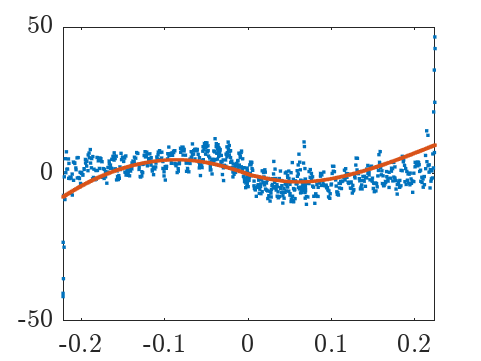



%% FITTING - PURE ALIGNING MOMENT
% initialise tyre data
tyre_coeffs_mz = initialise_tyre_data_ply(R0, Fz0);

%% Fitting with Fz=Fz_nom= 220N and camber=0  k = 0 VX= 10
% ------------------

FZ0 = mean(TData0_mz.FZ);

zeros_vec = zeros(size(TData0_mz.MZ));
ones_vec  = ones(size(TData0_mz.MZ));

MZ0_guess = MF96_MZ0_vec(zeros_vec, TData0_mz.SA, zeros_vec, tyre_coeffs_mz.FZ0*ones_vec, tyre_coeffs_mz);

% check guess 
figure()
plot(TData0_mz.SA,TData0_mz.MZ,'.')
hold on
plot(TData0_mz.SA,MZ0_guess,'.')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
%    {qBz1, qBz9, qBz10, qCz1, qDz1, qDz6, qEz1, qEz4, qHz1}
P0_mz = [  1,   1,   1,   1,   1,   1,   1,   1,   1 ];  % nostri buoni
% P0_mz = [  0,   1.5,   1,   1,   1.5,  0,   0,   0,   0 ];    % prove

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%    [pCx1 pDx1 pEx1 pEx4  pHx1  pKx1  pVx1 
% lb = [1,   0.1,   0,   0,  -10,    0,   -10];
% ub = [2,    4,   1,   1,   10,   100,  10];


ALPHA_vec = TData0_mz.SA;
MZ_vec    = TData0_mz.MZ;

% check guess
SA_vec = -12*to_rad:0.001:12*to_rad;
MZ0_fz_nom_vec = MF96_MZ0_vec(zeros(size(SA_vec)), SA_vec, zeros(size(SA_vec)), ...
                              FZ0.*ones(size(SA_vec)),tyre_coeffs_mz);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_fz_nom_vec,'.')
% 


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_fz_nom,fval,exitflag] = fmincon(@(P)resid_pure_Mz(P, MZ_vec, ALPHA_vec, 0, FZ0, tyre_coeffs_mz),...
                               P0_mz,[],[],[],[],[],[]);


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



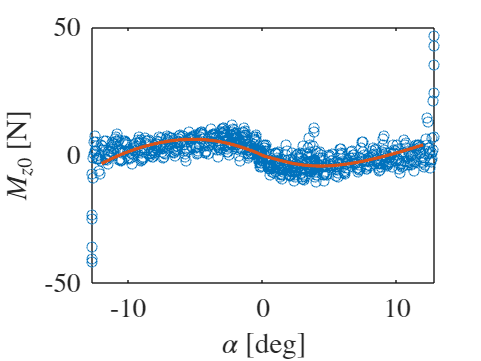


% Update tyre data with new optimal values                             

tyre_coeffs_mz.qBz1 = P_fz_nom(1); 
tyre_coeffs_mz.qBz9 = P_fz_nom(2);
tyre_coeffs_mz.qBz10 = P_fz_nom(3);
tyre_coeffs_mz.qCz1 = P_fz_nom(4);
tyre_coeffs_mz.qDz1 = P_fz_nom(5);
tyre_coeffs_mz.qDz6 = P_fz_nom(6);
tyre_coeffs_mz.qEz1 = P_fz_nom(7);
tyre_coeffs_mz.qEz4 = P_fz_nom(8);
tyre_coeffs_mz.qHz1 = P_fz_nom(9);

MZ0_fz_nom_vec = MF96_MZ0_vec(zeros(size(SA_vec)), SA_vec, zeros(size(SA_vec)), ...
                              FZ0.*ones(size(SA_vec)),tyre_coeffs_mz);

figure('Name','Mz0(Fz0)')
plot(TData0_mz.SA*to_deg, TData0_mz.MZ,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
plot(SA_vec*to_deg, MZ0_fz_nom_vec,'-','LineWidth',2)
xlabel('$\alpha$ [deg]')
ylabel('$M_{z0}$ [N]')

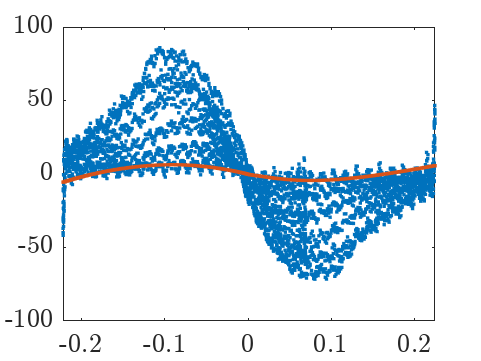


%% Fit coeefficient with variable load
% extract data with variable load
[TDataDFz_mz, ~] = intersect_table_data( SL_0, GAMMA_0 );
% lateral slip

% Fit the coeffs {qBz2, qBz3, qDz2, qDz7, qEz2, qEz3, qHz2}
%FZ0 = mean(TData0.FZ);

zeros_vec = zeros(size(TDataDFz_mz.SA));
ones_vec  = ones(size(TDataDFz_mz.SA));

MZ0_guess = MF96_MZ0_vec(zeros_vec, TDataDFz_mz.SA, zeros_vec, tyre_coeffs_mz.FZ0*ones_vec, tyre_coeffs_mz);

% check guess 
figure()
plot(TDataDFz_mz.SA,TDataDFz_mz.MZ,'.')
hold on
plot(TDataDFz_mz.SA,MZ0_guess,'.')


% Plot raw data and initial guess
% figure()
% plot(TDataSub.KAPPA,TDataSub.FX,'o')
% hold on
% plot(TDataSub.KAPPA,FX0_guess,'x')

% Guess values for parameters to be optimised
% [qBz2, qBz3, qDz2, qDz7, qEz2, qEz3, qHz2]

P0_mz_dFz = [ 0,  0,  0,  0,  0,  0,   0 ]; 

%P0_mz_dFz = [-0.70,	0.053, 0.008, -0.0087, 0.0012,-1.314e-4, 0.0968];
%P0_mz_dFz = [ -0.47e1,  -0.61e1,  -0.55e-1,  0.17e-1,  -0.17e1,  -0.33e1,   -0.33e-2 ]; 

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 

lb = [];
ub = [];


ALPHA_vec = TDataDFz_mz.SA;
mz_vec    = TDataDFz_mz.MZ;
FZ_vec    = TDataDFz_mz.FZ;

% check guess
SA_vec = -12*to_rad:0.001:12*to_rad;
MZ0_dfz_vec = MF96_MZ0_vec(zeros(size(SA_vec)), SA_vec, zeros(size(SA_vec)), ...
                           FZ_vec, tyre_coeffs_mz);
% 
% figure
% plot(KAPPA_vec,FX_vec,'.')
% hold on
% plot(SL_vec,FX0_dfz_vec,'.')


% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 

[P_dfz_mz,fval,exitflag] = fmincon(@(P)resid_pure_Mz_varFz(P, mz_vec, ALPHA_vec, 0, FZ_vec, tyre_coeffs_mz),...
                               P0_mz_dFz,[],[],[],[],lb,ub);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



disp(exitflag)

     2




% Change tyre data with new optimal values                             
% tyre_coeffs_mz.qBz2 = P_dfz_mz(1); 
% tyre_coeffs_mz.qBz3 = P_dfz_mz(2);
% tyre_coeffs_mz.qDz2 = P_dfz_mz(3);
% tyre_coeffs_mz.qDz7 = P_dfz_mz(4);
% tyre_coeffs_mz.qEz2 = P_dfz_mz(5);
% tyre_coeffs_mz.qEz3 = P_dfz_mz(6);
% tyre_coeffs_mz.qHz2 = P_dfz_mz(7);

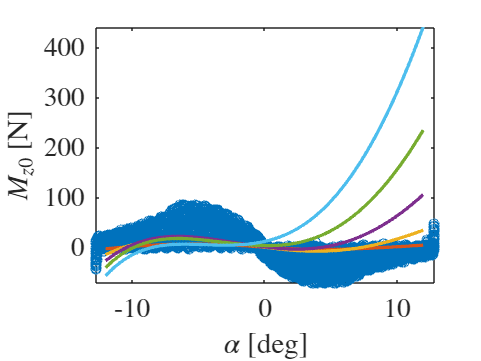


tyre_coeffs_mz.qBz2 = 0.004;
tyre_coeffs_mz.qBz3 = .003;
tyre_coeffs_mz.qDz2 = -0.6;
tyre_coeffs_mz.qDz7 = 0.013;
tyre_coeffs_mz.qEz2 = 214;
tyre_coeffs_mz.qEz3 = 0.0013;
tyre_coeffs_mz.qHz2 = 0.003;


%res_MZ0_dfz_vec = resid_pure_Mz_varFz(P_dfz_mz, mz_vec, SA_vec, 0 , FZ_vec, tyre_coeffs_mz);

tmp_zeros = zeros(size(SA_vec));
tmp_ones = ones(size(SA_vec));


MZ0_fz_var_vec1 = MF96_MZ0_vec(tmp_zeros, SA_vec, tmp_zeros, mean(FZ_220.FZ)*tmp_ones,tyre_coeffs_mz);
MZ0_fz_var_vec2 = MF96_MZ0_vec(tmp_zeros, SA_vec, tmp_zeros, mean(FZ_440.FZ)*tmp_ones,tyre_coeffs_mz);
MZ0_fz_var_vec3 = MF96_MZ0_vec(tmp_zeros, SA_vec, tmp_zeros, mean(FZ_700.FZ)*tmp_ones,tyre_coeffs_mz);
MZ0_fz_var_vec4 = MF96_MZ0_vec(tmp_zeros, SA_vec, tmp_zeros, mean(FZ_900.FZ)*tmp_ones,tyre_coeffs_mz);
MZ0_fz_var_vec5 = MF96_MZ0_vec(tmp_zeros, SA_vec, tmp_zeros, mean(FZ_1120.FZ)*tmp_ones,tyre_coeffs_mz);


figure('Name','Mz0(Fz0)')
plot(TDataDFz_mz.SA*to_deg,TDataDFz_mz.MZ,'o')
hold on
%plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
%plot(SL_vec,FX0_dfz_vec,'-','LineWidth',2)
plot(SA_vec*to_deg,MZ0_fz_var_vec1,'-','LineWidth',2)
plot(SA_vec*to_deg,MZ0_fz_var_vec2,'-','LineWidth',2)
plot(SA_vec*to_deg,MZ0_fz_var_vec3,'-','LineWidth',2)
plot(SA_vec*to_deg,MZ0_fz_var_vec4,'-','LineWidth',2)
plot(SA_vec*to_deg,MZ0_fz_var_vec5,'-','LineWidth',2)

xlabel('$\alpha$ [deg]')
ylabel('$M_{z0}$ [N]')

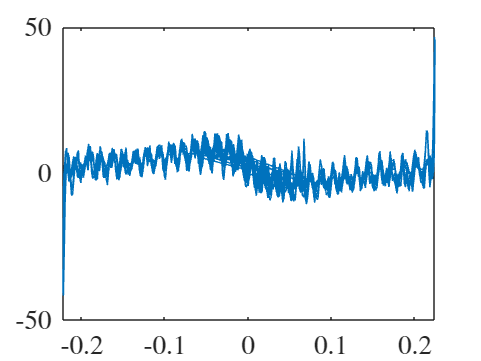



% [alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_220.FZ), tyre_coeffs);
% Calfa_vec1_0 = Kya;
% [alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_440.FZ), tyre_coeffs);
% Calfa_vec2_0 = Kya;
% [alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_700.FZ), tyre_coeffs);
% Calfa_vec3_0 = Kya;
% [alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_900.FZ), tyre_coeffs);
% Calfa_vec4_0 = Kya;
% [alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_1120.FZ), tyre_coeffs);
% Calfa_vec5_0 = Kya;
% % 
% Calfa_vec1 = MF96_CorneringStiffness(SA_vec,tmp_zeros ,tmp_zeros, mean(FZ_220.FZ)*tmp_ones,tyre_coeffs);
% Calfa_vec2 = MF96_CorneringStiffness(SA_vec,tmp_zeros ,tmp_zeros, mean(FZ_440.FZ)*tmp_ones,tyre_coeffs);
% Calfa_vec3 = MF96_CorneringStiffness(SA_vec,tmp_zeros ,tmp_zeros, mean(FZ_700.FZ)*tmp_ones,tyre_coeffs);
% Calfa_vec4 = MF96_CorneringStiffness(SA_vec,tmp_zeros ,tmp_zeros, mean(FZ_900.FZ)*tmp_ones,tyre_coeffs);
% Calfa_vec5 = MF96_CorneringStiffness(SA_vec,tmp_zeros ,tmp_zeros, mean(FZ_1120.FZ)*tmp_ones,tyre_coeffs);
% 
% figure('Name','C_alpha')
% subplot(2,1,1)
% hold on
% %plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
% plot(mean(FZ_220.FZ),Calfa_vec1_0,'+','LineWidth',2)
% plot(mean(FZ_440.FZ),Calfa_vec2_0,'+','LineWidth',2)
% plot(mean(FZ_700.FZ),Calfa_vec3_0,'+','LineWidth',2)
% plot(mean(FZ_900.FZ),Calfa_vec4_0,'+','LineWidth',2)
% plot(mean(FZ_1120.FZ),Calfa_vec5_0,'+','LineWidth',2)
% legend({'$Fz_{220}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})

% subplot(2,1,2)
% hold on
% %plot(TDataSub.KAPPA,FX0_fz_nom_vec,'-')
% plot(SL_vec,Calfa_vec1,'-','LineWidth',2)
% plot(SL_vec,Calfa_vec2,'-','LineWidth',2)
% plot(SL_vec,Calfa_vec3,'-','LineWidth',2)
% plot(SL_vec,Calfa_vec4,'-','LineWidth',2)
% legend({'$Fz_{220}$','$Fz_{700}$','$Fz_{900}$','$Fz_{1120}$'})


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Fit coefficient with variable camber


SA_tol = 0.5*to_rad;
idx.SA_0    =  0-SA_tol          < tyre_data.SA & tyre_data.SA < 0+SA_tol;
idx.SA_3neg = -(3*to_rad+SA_tol) < tyre_data.SA & tyre_data.SA < -3*to_rad+SA_tol;
idx.SA_6neg = -(6*to_rad+SA_tol) < tyre_data.SA & tyre_data.SA < -6*to_rad+SA_tol;
SA_0_LAT     = tyre_data( idx.SA_0, : );

% extract data with variable load
[TDataGamma_mz, ~] = intersect_table_data(SL_0, FZ_220);

% Extract points at constant camber and plot
GAMMA_tol_mz_dgamma = 0.05*to_rad;
idx_pl_dgamma.GAMMA_0 = 0.0*to_rad-GAMMA_tol_mz_dgamma < TDataGamma_mz.IA & TDataGamma_mz.IA < 0.0*to_rad+GAMMA_tol_mz_dgamma;
idx_pl_dgamma.GAMMA_1 = 1.0*to_rad-GAMMA_tol_mz_dgamma < TDataGamma_mz.IA & TDataGamma_mz.IA < 1.0*to_rad+GAMMA_tol_mz_dgamma;
idx_pl_dgamma.GAMMA_2 = 2.0*to_rad-GAMMA_tol_mz_dgamma < TDataGamma_mz.IA & TDataGamma_mz.IA < 2.0*to_rad+GAMMA_tol_mz_dgamma;
idx_pl_dgamma.GAMMA_3 = 3.0*to_rad-GAMMA_tol_mz_dgamma < TDataGamma_mz.IA & TDataGamma_mz.IA < 3.0*to_rad+GAMMA_tol_mz_dgamma;
idx_pl_dgamma.GAMMA_4 = 4.0*to_rad-GAMMA_tol_mz_dgamma < TDataGamma_mz.IA & TDataGamma_mz.IA < 4.0*to_rad+GAMMA_tol_mz_dgamma;

GAMMA_0_dgamma  = TDataGamma_mz( idx_pl_dgamma.GAMMA_0, : );
GAMMA_1_dgamma  = TDataGamma_mz( idx_pl_dgamma.GAMMA_1, : );
GAMMA_2_dgamma  = TDataGamma_mz( idx_pl_dgamma.GAMMA_2, : );
GAMMA_3_dgamma  = TDataGamma_mz( idx_pl_dgamma.GAMMA_3, : );
GAMMA_4_dgamma  = TDataGamma_mz( idx_pl_dgamma.GAMMA_4, : );


% Fit the coeffs { qBz4, qBz5, qDz3, qDz4, qEz5, qDz8, qDz9, qHz3, qHz4 }
% Guess values for parameters to be optimised
P0_gamma_mz = [1, 0, 0, 0, 0, 0, 0, 0, 0];

% NOTE: many local minima => limits on parameters are fundamentals
% Limits for parameters to be optimised
% 1< pCx1 < 2 
% 0< pEx1 < 1 
%lb = [0, 0,  0, 0,  0,  0,  0];
%ub = [2, 1e6,1, 1,1e1,1e2,1e2];
lb = [-100, -0.1, -0.1, -0.1, -0.1, -0.1, -0.1, -0.1, -0.1];
ub = [100, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1];


zeros_vec = zeros(size(TDataGamma_mz.IA));
ones_vec  = ones(size(TDataGamma_mz.IA));

ALPHA_vec = TDataGamma_mz.SA;
GAMMA_vec = TDataGamma_mz.IA; 
MZ_vec    = TDataGamma_mz.MZ;
FZ_vec    = TDataGamma_mz.FZ;

figure()
plot(ALPHA_vec, MZ_vec);



% LSM_pure_Fx returns the residual, so minimize the residual varying X. It
% is an unconstrained minimization problem 
[P_varGamma_mz,fval,exitflag] = fmincon(@(P)resid_pure_Mz_varGamma(P,MZ_vec, ALPHA_vec,GAMMA_vec,tyre_coeffs.FZ0, tyre_coeffs_mz),...
                               P0_gamma_mz,[],[],[],[],lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


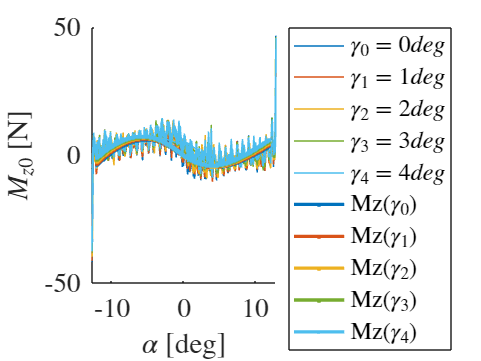


% Change tyre data with new optimal values       

tyre_coeffs_mz.qBz4 = P_varGamma_mz(1); 
tyre_coeffs_mz.qBz5 = P_varGamma_mz(2);
tyre_coeffs_mz.qDz3 = P_varGamma_mz(3);
tyre_coeffs_mz.qDz4 = P_varGamma_mz(4);
tyre_coeffs_mz.qEz5 = P_varGamma_mz(5);
tyre_coeffs_mz.qDz8 = P_varGamma_mz(6);
tyre_coeffs_mz.qDz9 = P_varGamma_mz(7);
tyre_coeffs_mz.qHz3 = P_varGamma_mz(8);
tyre_coeffs_mz.qHz4 = P_varGamma_mz(9);

% FY0_varGamma_vec = MF96_FY0_vec(zeros_vec, ALPHA_vec, GAMMA_vec, tyre_coeffs_mz.FZ0*ones_vec,tyre_coeffs_mz);
% 
% figure('Name','Fy0 vs Gamma')
% plot(ALPHA_vec*to_deg,TDataGamma.FY,'o')
% hold on
% plot(ALPHA_vec*to_deg,FY0_varGamma_vec,'.')
% xlabel('$\alpha$ [deg]')
% ylabel('$F_{y0}$ [N]')

MZ0_gamma_var_vec1 = MF96_MZ0_vec(zeros_vec, SA_vec ,mean(GAMMA_0_dgamma.IA)*ones_vec, mean(TDataGamma.FZ)*ones_vec,tyre_coeffs_mz);
MZ0_gamma_var_vec2 = MF96_MZ0_vec(zeros_vec, SA_vec ,mean(GAMMA_1_dgamma.IA)*ones_vec, mean(TDataGamma.FZ)*ones_vec,tyre_coeffs_mz);
MZ0_gamma_var_vec3 = MF96_MZ0_vec(zeros_vec, SA_vec ,mean(GAMMA_2_dgamma.IA)*ones_vec, mean(TDataGamma.FZ)*ones_vec,tyre_coeffs_mz);
MZ0_gamma_var_vec4 = MF96_MZ0_vec(zeros_vec, SA_vec ,mean(GAMMA_3_dgamma.IA)*ones_vec, mean(TDataGamma.FZ)*ones_vec,tyre_coeffs_mz);
MZ0_gamma_var_vec5 = MF96_MZ0_vec(zeros_vec, SA_vec ,mean(GAMMA_4_dgamma.IA)*ones_vec, mean(TDataGamma.FZ)*ones_vec,tyre_coeffs_mz);


figure()
hold on
plot(GAMMA_0_dgamma.SA*to_deg,GAMMA_0_dgamma.MZ,'-','MarkerSize',5, 'Color', '#0072BD') %'MarkerEdgeColor','y',
plot(GAMMA_1_dgamma.SA*to_deg,GAMMA_1_dgamma.MZ,'-','MarkerSize',5, 'Color', '#D95319') %'MarkerEdgeColor','c',
plot(GAMMA_2_dgamma.SA*to_deg,GAMMA_2_dgamma.MZ,'-','MarkerSize',5, 'Color', '#EDB120') %'MarkerEdgeColor','m',
plot(GAMMA_3_dgamma.SA*to_deg,GAMMA_3_dgamma.MZ,'-','MarkerSize',5, 'Color', '#77AC30') %'MarkerEdgeColor','b',
plot(GAMMA_4_dgamma.SA*to_deg,GAMMA_4_dgamma.MZ,'-','MarkerSize',5, 'Color', '#4DBEEE') %'MarkerEdgeColor','r',
plot(SA_vec*to_deg,MZ0_gamma_var_vec1,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#0072BD')
plot(SA_vec*to_deg,MZ0_gamma_var_vec2,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#D95319')
plot(SA_vec*to_deg,MZ0_gamma_var_vec3,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#EDB120')
plot(SA_vec*to_deg,MZ0_gamma_var_vec4,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#77AC30')
plot(SA_vec*to_deg,MZ0_gamma_var_vec5,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#4DBEEE')
legend({'$ \gamma_0 = 0 deg $','$ \gamma_1 = 1 deg $','$ \gamma_2 = 2 deg $','$ \gamma_3 = 3 deg$','$ \gamma_4 = 4 deg $', 'Mz($\gamma_0$)','Mz($\gamma_1$)','Mz($\gamma_2$)','Mz($\gamma_3$)','Mz($\gamma_4$)'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$M_{z0}$ [N]')



% Calculate the residuals with the optimal solution found above
res_Mz0_varGamma  = resid_pure_Mz_varGamma(P_varGamma_mz,MZ_vec, ALPHA_vec, GAMMA_vec, tyre_coeffs_mz.FZ0, tyre_coeffs_mz);

% % R-squared is 
% % 1-SSE/SST
% % SSE/SST = res_Fx0_nom
% 
% % SSE is the sum of squared error,  SST is the sum of squared total
% fprintf('R-squared = %6.3f\n',1-res_Fx0_varGamma);
% 
% 
% [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, GAMMA_vec(3), tyre_coeffs.FZ0, tyre_coeffs);
% % 
% fprintf('Bx      = %6.3f\n',Bx);
% fprintf('Cx      = %6.3f\n',Cx);
% fprintf('mux      = %6.3f\n',Dx/tyre_coeffs.FZ0);
% fprintf('Ex      = %6.3f\n',Ex);
% fprintf('SVx     = %6.3f\n',SVx);
% fprintf('kappa_x = %6.3f\n',kappa__x);
% fprintf('Kx      = %6.3f\n',Bx*Cx*Dx/tyre_coeffs.FZ0);

% % Longitudinal stiffness
% Kx_vec = zeros(size(load_vec));
% for i = 1:length(load_vec)
%   [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, 0, load_vec(i), tyre_data);
%   Kx_vec(i) = Bx*Cx*Dx/tyre_data.Fz0;
% end
% 
% figure('Name','Kx vs Fz')
% plot(load_vec,Kx_vec,'o-')

%% Save tyre data structure to mat file
%
save(['tyre_' data_set,'.mat'],'tyre_coeffs_mz');



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

